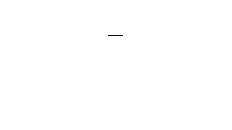

f = imread("Important_files/cameraman.tif");

h = fspecial('motion', 15);

imshow(h, []);

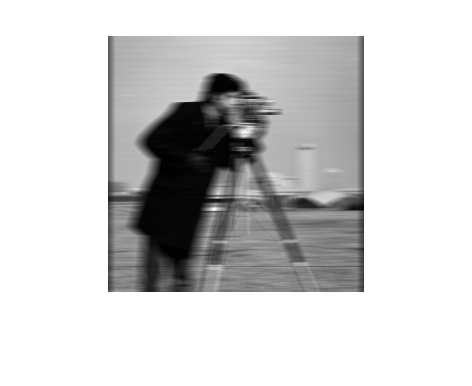


g = imfilter(double(f), h, 'conv');

imshow(g, []);

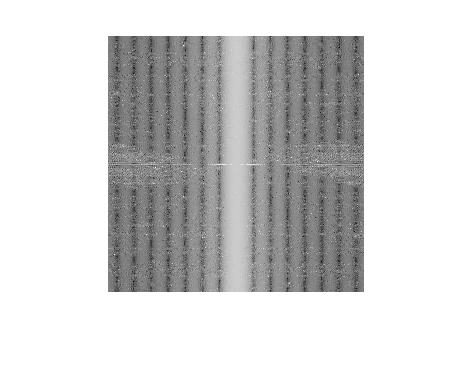

G = fft2(g);
F = fft2(f);

%imshow(log(abs(G)), []);
%imshow(log(abs(F)), []);

%psf(find(abs(psf) == 0)) = 0.001;

H = G ./ F;
imshow(log(abs(fftshift(H))), []);

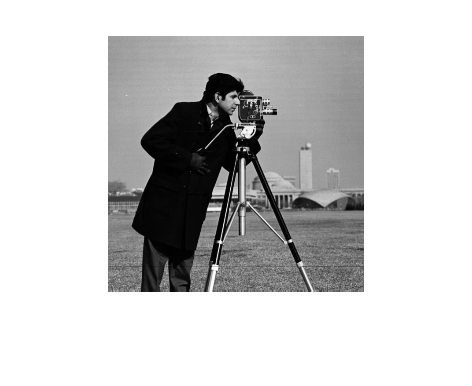

im_restored = (ifft2(G./H));
imshow(im_restored,[]);

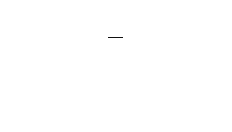

h_est = fspecial('motion', 15);
%h_est = fspecial('motion', 15, 10);

imshow(h_est, []);

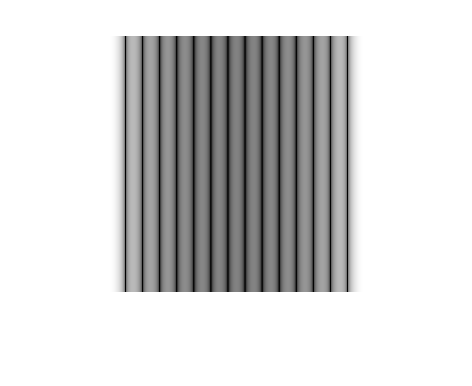


H_est = psf2otf(h_est, [256,256]);
H_est(find(abs(H_est) == 0)) = 0.001;
imshow(log(abs(H_est)), []);

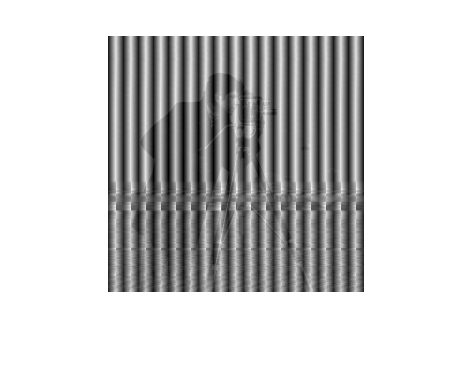

im_restored = ifft2(G./H_est);
imshow(im_restored,[]);

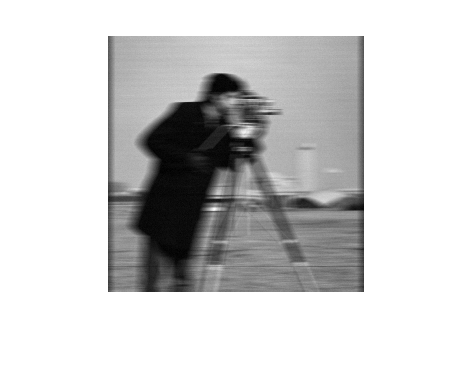

noise = normrnd(0,2,256,256);

g_noise = g + noise;

G_noise = fft2(g_noise);

imshow(g_noise, [])

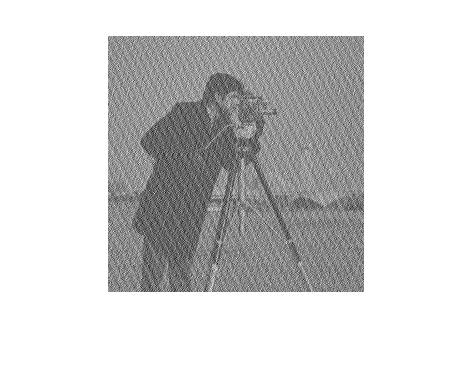


im_restored = (ifft2(G_noise./H));
imshow(im_restored,[]);

%NP = abs(fftn(noise)).^2
%NCORR = fftshift(real(ifftn(NP)))

im_restored = deconvwnr(g_noise, real(fftshift(ifft2(H))), noise, g);
imshow(im_restored,[]);